# AE 6353 HW 2 - Orbit Determination, Mean and Eccentric Anomaly

% Author: Albert Zheng
% Date: 9/13/24

% MATLAB code used for AE6353 HW1
% Local functions are appended to the end of this script

clear;clc;close all

## Question 2

% Convert position/velocity to orbital elements
r = [6045;3490;0].*1000; % m
v = [-2.457; 6.618; 2.533].*1000; % m/s

COE = IJKtoCOE(r,v) % [a eNorm i RAAN omega f]

COE = 1.0e+06 *

   6.877257453171985
   0.000000158170584
   0.000000349042397
   0.000000523588555
   0.000004460729807
   0.000001822455501


[r2,v2] = COEtoIJK(COE)

r2 = 1.0e+06 *

   6.045000000000000
   3.490000000000002
   0.000000000000000


v2 = 1.0e+03 *

  -2.457000000000002
   6.617999999999998
   2.532999999999999


% As shown by the outputs of IJKtoCOE and COEtoIJK, reversibility between position and velocity in ECI (IJK) and orbital elements
% is proven to be true

## Question 3

clear;clc

% Solve Newton-Raphson method - not working
M = 0.6;
e = 0.7;
tol = 1e-6;
Einit = 5;

[E,f] = keplersEqn(M,e,tol,Einit)

E =    1.268195201148072


f =    2.103607909491014


## Question 4

clear;clc;close all

format shortG

% Get orbital element info from TLE

figure(1)
name = "ISS (ZARYA)";
line1 = "1 25544U 98067A 20216.49005787 .00002416 00000-0 51722-4 0 9995";
line2 = "2 25544 51.6454 114.3468 0000873 353.4400 1.0119 15.49140402239344";
line1 = strsplit(line1);
line2 = strsplit(line2);

% Orbit Inclination (degrees to rad)
incl = deg2rad(str2double(line2(3)));
% Right Ascension of Ascending Node (RAAN) (degrees to rad)
Omega = deg2rad(str2double(line2(4)));
% Eccentricity
e = str2double(line2(5))*1E-7;
% Argument of Perigee (degrees to rad)
w = deg2rad(str2double(line2(6)));
% Mean Anomaly (degrees to rad)
M = deg2rad(str2double(line2(7)));
% Mean Motion (revolutions/day to rad/s)
n = str2double(line2(8)) * ((2*pi)/(86400));

% Get a
mu = 3.986e14; % (m^3 * s^-2), for earth
a = (mu/n^2)^(1/3);

% Get f
tol = 1e-6;
Einit = M;
[~,f] = keplersEqn(M,e,tol,Einit); % re use function from Q3

% 4a - Get position and velicty from ISS (ZARYA)
[r_ISS,v_ISS] = COEtoIJK([a e incl Omega w f])

r_ISS =   -2.4174e+06
   6.3314e+06
  -5.1529e+05


v_ISS =       -4614.5
      -1275.4
       5977.4


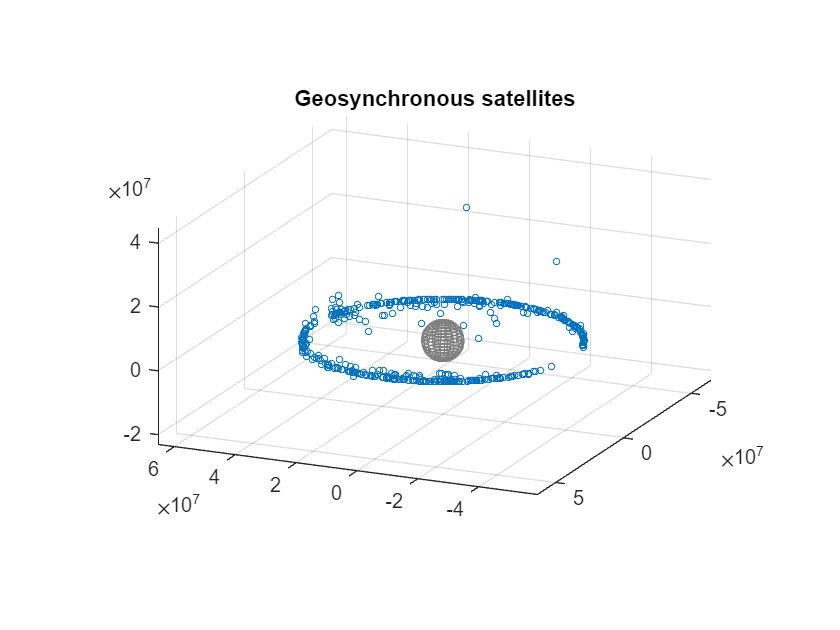

clear;clc;close all

% 4b - Generalize code to accept multiple entries at once

% Get data from txt file
fid = fopen('geosyncTLE.txt', 'r'); % open file
lines = {};

% Read the file line by line
while ~feof(fid)
    line = fgetl(fid);  % Get the next line as a string
    lines{end+1} = line;  % Append the line to the cell array
end

% Close the file
fclose(fid);

mu = 3.986e14; % (m^3 * s^-2), for earth

positions = zeros(length(lines)/3,3);
velocities = zeros(length(lines)/3,3);

for i = 3:3:length(lines) % get every 3rd row (3,6,9,...)
    line = lines{i};
    line = strsplit(line);

    % Orbit Inclination (degrees to rad)
    incl = deg2rad(str2double(line{3}));
    % Right Ascension of Ascending Node (RAAN) (degrees to rad)
    Omega = deg2rad(str2double(line{4}));
    % Eccentricity
    e = str2double(line{5})*1E-7;
    % Argument of Perigee (degrees to rad)
    w = deg2rad(str2double(line{6}));
    % Mean Anomaly (degrees to rad)
    M = deg2rad(str2double(line{7}));
    % Mean Motion (revolutions/day to rad/s)
    n = str2double(line{8}) * ((2*pi)/(86400));
    
    % Get a
    a = (mu/n^2)^(1/3);
    
    % Get f
    tol = 1e-6;
    Einit = M;
    [~,f] = keplersEqn(M,e,tol,Einit); % re use function from Q3

    [r_ISS,v_ISS] = COEtoIJK([a e incl Omega w f]);

    positions(i/3,:) = r_ISS';
    velocities(i/3,:) = v_ISS';

end
% Plot satellites

figure(1)

npanels = 20;
erad = 6378.1; % equatorial radius (km)
prad = 6356.8; % polar radius (km)
axis(2e4*[-1 1 -1 1 -1 1]);
view(9,26);
hold on;
axis vis3d;
[xx yy zz] = ellipsoid(0,0,0,erad*1000,erad*1000,prad*1000,npanels); % scale earth by 100 for visibility
globe = surf(xx,yy,-zz,'FaceColor','none','EdgeColor',0.5*[1 1 1]);
size = 10;  % Circle size
scatter3(positions(:,1),positions(:,2),positions(:,3),size,'o')
% plot3(positions(:,1),positions(:,2),positions(:,3))
title('Geosynchronous satellites')
axis equal
grid on
xlim([-59247279 65075326])
ylim([-63974703 63130214])
zlim([-23150856 45029201])

view([204 17])

## Local functions

### IJKtoCOE

function COE = IJKtoCOE(r,v)
% IJKtoCOE Converts position and velocity in ECI to classical orbital elements
% 
% rs - position (3x1) (m)
% v - velocity (3x1) (m/s)
% COE - classical orbital elements - [a e i bigOmega omega f]
%   a = semi major axis (m)
%   eNorm = eccentricity (m)
%   i = inclination (rad)
%   RAAN = right ascension of ascending node (rad)
%   omega = argument of periapsis (rad)
%   f = true anomaly (rad)
%
% TODO add the following orbital elements: arg of lat at epoch, long of
% periapsis, true longitude of epoch

    mu = 3.986e14; % (m^3 * s^-2), for earth
    vNorm = norm(v);
    rNorm = norm(r);
    eps = 0.5*(vNorm^2) - mu/rNorm; % specific energy
    h = cross(r,v); % angular momentum
    e = (1/mu) .* (cross(v,h) - (mu.*r)./rNorm); % eccentricity vector
    k = [0;0;1]; % k direction
    n = cross(k,h)./norm(cross(k,h)); % line of ascending node unit vector

    % Calculate classical orbital elements

    % Semi major axis
    a = -mu/(2*eps);

    % Eccentricity
    eNorm = norm(e);

    % Inclination
    i = acos(h(3)/norm(h)); % 0 <= i <= pi

    % Right ascension of ascending node
    % RAAN = acos(n(1)/norm(n));
    RAAN = atan2(n(2),n(1));

    % Argument of periapsis
    if dot(e,k) >= 0 % eccentricity is pointing above equator (z-comp is positive)
        omega = acos(dot(n,e)/norm(e)); % 0 <= omega <= pi
    else % eccentricity is pointing below equator
        omega = 2*pi - acos(dot(n,e)/norm(e)); % pi < f < 2pi
    end

    % True anomaly
    if dot(r,v) >= 0 % is radius vector increasing over time?
        f = acos( dot(e,r)/(eNorm*rNorm) ); % 0 <= f <= pi
    else % decreasing over time
        f = 2*pi - acos( dot(e,r)/(eNorm*rNorm) ); % pi < f < 2pi
    end

    COE = [a;eNorm;i;RAAN;omega;f];

    [r_ISS,v_ISS] = COEtoIJK([a e incl Omega w f])
    
end

### COEtoIJK

function [r_eci,v_eci] = COEtoIJK(COE)
% COEtoIJK Converts classical orbital elements to position and velocity in
% ECI
% 
% COE - classical orbital elements - [a e i bigOmega omega f]
%   a = semi major axis (m)
%   eNorm = eccentricity (m)
%   i = inclination (rad)
%   RAAN = right ascension of ascending node (rad)
%   omega = argument of periapsis (rad)
%   f = true anomaly (rad)
% p - position (3x1) (m)
% v - velocity (3x1) (m/s)

    mu = 3.986e14; % (m^3 * s^-2), for earth

    % Extract orbital elements from input
    a = COE(1);
    eNorm = COE(2);
    i = COE(3);
    RAAN = COE(4);
    omega = COE(5);
    f = COE(6);

    % Get r and v in perifocal frame

    p = a*(1-eNorm^2);
    rNorm = p/(1+eNorm*cos(f));

    r_peri = [rNorm*cos(f);
              rNorm*sin(f);
              0];
    
    v_peri = sqrt(mu/p) .* [-sin(f);
                            eNorm + cos(f);
                            0];

    % Convert from perifocal to ECI
    R_RAAN = [cos(RAAN) -sin(RAAN) 0;
               sin(RAAN) cos(RAAN) 0;
               0            0        1];
    R_i = [1 0 0;
           0 cos(i) -sin(i);
           0 sin(i) cos(i)];
    R_omega = [cos(omega) -sin(omega) 0;
               sin(omega) cos(omega) 0;
               0            0        1];
    r_eci = (R_RAAN * R_i * R_omega) * r_peri;
    v_eci = (R_RAAN * R_i * R_omega) * v_peri;
    
end

### keplersEqn - Use Newton-Raphson to get E and f from M

function [E,f] = keplersEqn(M,e,tol,Einit)
% keplersEqn Finds eccentric anomaly E and true anomaly f from mean anomaly
% M using Newton-Raphson method
%
% e - eccentricity
% M - mean anomaly

g = @(E) E - e*sin(E) - M;
gDot = @(E) 1 - e*cos(E);

% Find E from M
firstIteration = true;
while true

    if (~firstIteration)
        E_curr = E_next;
    else
        E_curr = Einit;
        firstIteration = false;
    end

    E_next = E_curr - g(E_curr)/gDot(E_curr);

%     fprintf('%d\n',abs(g(E_curr)))
    if abs(g(E_curr)) < tol
        E = E_curr;
        break
    end

end

% Find f from E
% f = 2*atan(sqrt( (1+e)/(1-e) ) * tan(E/2));
f = 2*atan2(sqrt( (1+e)/(1-e) ) * tan(E/2), 1);


end